# Exercises 7.2

5. (Opt.) Find all shape functions for the transition element shown below.

6. (Opt.) Using computer software plot the shape functions of nodes 1 and 5 for the element in the last exercise.

clear all 
clc

syms xi eta a b x

% ELEMENTO DE TRANSIÇÃO QUADRILATERAL COM 5 NÓS
NC =  1/4 * (1 + xi*a) * (1 + eta*b);    % i = 1...4 (linear)
NMP = 1/2 * (1 + xi*a) * (1 - eta^2);    % i = 6, 8  (quadratico)
NMI = 1/2 * (1 + xi^2) * (1 - eta*b);    % i = 5, 7  (quadratico)

N1 = subs (NC,  [a b], [-1 -1])

$$N1 = \left(\frac{\xi }{4}-\frac{1}{4}\right)\,\left(\eta -1\right)$$

N2 = subs (NC,  [a b], [ 1 -1])

$$N2 = -\left(\frac{\xi }{4}+\frac{1}{4}\right)\,\left(\eta -1\right)$$

N3 = subs (NC,  [a b], [ 1  1])

$$N3 = \left(\frac{\xi }{4}+\frac{1}{4}\right)\,\left(\eta +1\right)$$

N4 = subs (NC,  [a b], [-1  1])

$$N4 = -\left(\frac{\xi }{4}-\frac{1}{4}\right)\,\left(\eta +1\right)$$

N5 = subs (NMP, [a b], [ 1  0])

$$N5 = -\left(\eta^{2}-1\right)\,\left(\frac{\xi }{2}+\frac{1}{2}\right)$$

k=sum(N1+N2+N3+N4+N5)

$$k = \left(\frac{\xi }{4}-\frac{1}{4}\right)\,\left(\eta -1\right)-\left(\frac{\xi }{4}-\frac{1}{4}\right)\,\left(\eta +1\right)-\left(\frac{\xi }{4}+\frac{1}{4}\right)\,\left(\eta -1\right)+\left(\frac{\xi }{4}+\frac{1}{4}\right)\,\left(\eta +1\right)-\left(\eta^{2}-1\right)\,\left(\frac{\xi }{2}+\frac{1}{2}\right)$$

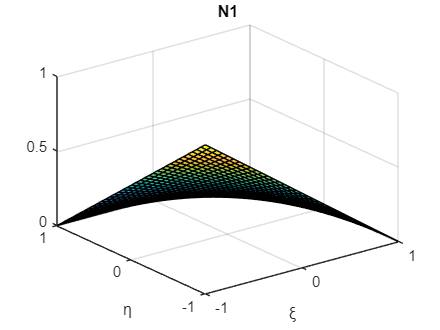

fsurf(N1,[-1 1 -1 1])
title 'N1'
xlabel ("ξ");
ylabel ("η");

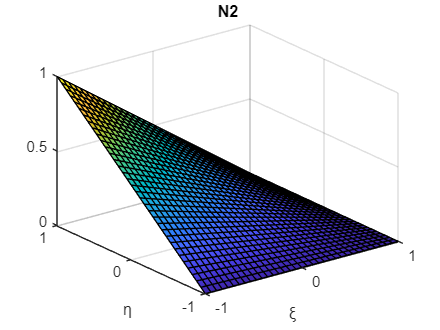

fsurf(N2,[-1 1 -1 1])
title 'N2'
xlabel ("ξ");
ylabel ("η");

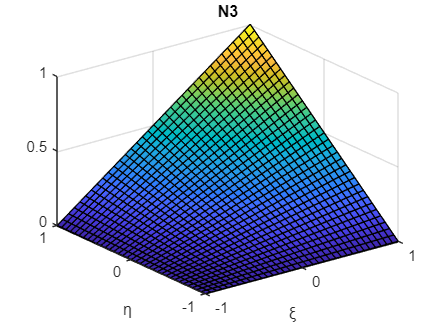

fsurf(N3,[-1 1 -1 1])
title 'N3'
xlabel ("ξ");
ylabel ("η");

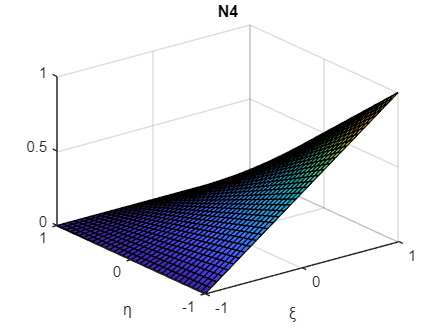

fsurf(N4,[-1 1 -1 1])
title 'N4'
xlabel ("ξ");
ylabel ("η");

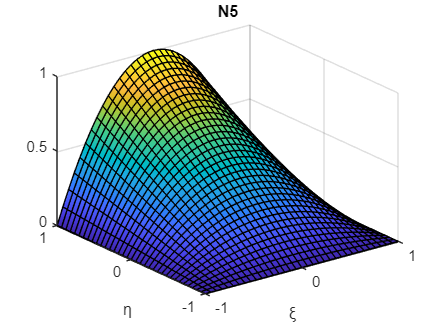

fsurf(N5,[-1 1 -1 1])
title 'N5'
xlabel ("ξ");
ylabel ("η");